# Work with Basic ROS Messages

This example shows various ways to create, explore, and populate ROS messages in MATLAB®, that are commonly encountered in robotics applications.

Messages are the primary container for exchanging data in ROS. Topics  and services  use messages to carry data between nodes. (See [Exchange Data with ROS Publishers and Subscribers](docid:ros_ug.mw_fa34dc6f-351e-4ab5-8680-46563496814b) and [Call and Provide ROS Services](docid:ros_ug.mw_70dbf089-5821-4e67-b96f-f659aea10c0c) for more information on topics and services)

Prerequisites: [Get Started with ROS](docid:ros_ug.mw_cb3fdf75-613d-45b1-90e1-aad102b9a24a), [Connect to a ROS Network](docid:ros_ug.mw_d625a603-7f37-4925-9470-2de734937434)

To identify its data structure, each message has a *message type*. For example, sensor data from a laser scanner is typically sent in a message of type `sensor_msgs/LaserScan`. Each message type identifies the data elements that are contained in a message. Every message type name is a combination of a package name, followed by a forward slash /, and a type name:

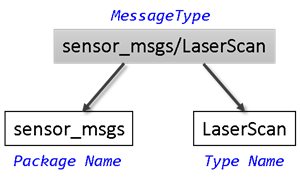

## Find Message Types

Initialize the ROS master and global node.

rosinit

Launching ROS Core...
..Done in 2.188 seconds.
Initializing ROS master on http://172.30.135.126:57071.
Initializing global node /matlab_global_node_67133 with NodeURI http://bat6326win64:49525/ and MasterURI http://localhost:57071.


Use `exampleHelperROSCreateSampleNetwork` to populate the ROS network with three additional nodes and sample publishers and subscribers.

exampleHelperROSCreateSampleNetwork

There are various nodes on the network with a few topics and affiliated publishers and subscribers.

You can see the full list of available topics by calling [`rostopic`](docid:ros_ref.bupf5_j_14)` list`.

rostopic list

/pose  
/rosout
/scan  
/tf    


If you want to know more about the type of data that is sent through the `/scan` topic, use the `rostopic info` command to examine it. `/scan` has a message type of `sensor_msgs/LaserScan`.

rostopic info /scan

Type: sensor_msgs/LaserScan
 
Publishers:
* /node_3 (http://bat6326win64:49546/)
 
Subscribers:
* /node_1 (http://bat6326win64:49533/)
* /node_2 (http://bat6326win64:49538/)


The command output also tells you which nodes are publishing and subscribing to the topic. To learn about publishers and subscribers, see [Exchange Data with ROS Publishers and Subscribers](docid:ros_ug.mw_70dbf089-5821-4e67-b96f-f659aea10c0c).

To find out more about the topic's message type, create an empty message of the same type using the [`rosmessage`](docid:ros_ref.bupf5_j_2) function. `rosmessage` supports tab completion for the message type. To complete message type names, type the first few characters of the name you want to complete, and then press the **Tab** key.

For better efficiency when creating messages or communicating, use messages in structure format.

scandata = rosmessage("sensor_msgs/LaserScan","DataFormat","struct")

scandata = struct with fields:
       MessageType: 'sensor_msgs/LaserScan'
            Header: [1×1 struct]
          AngleMin: 0
          AngleMax: 0
    AngleIncrement: 0
     TimeIncrement: 0
          ScanTime: 0
          RangeMin: 0
          RangeMax: 0
            Ranges: [0×1 single]
       Intensities: [0×1 single]


The created message `scandata` has many properties associated with data typically received from a laser scanner. For example, the minimum sensing distance is stored in the `RangeMin` field, and the maximum sensing distance is in `RangeMax`.

To see a complete list of all message types available for topics and services, use [`rosmsg`](docid:ros_ref.bupf5_j_3)` list`.

## Explore Message Structure and Get Message Data

ROS messages are structures, and the message data is stored in the fields of the structures. MATLAB features convenient ways to find and explore the contents of messages. 

- If you subscribe to the `/pose` topic, you can receive and examine the messages that are sent.

posesub = rossubscriber("/pose","DataFormat","struct")

posesub =   Subscriber with properties:

        TopicName: '/pose'
    LatestMessage: []
      MessageType: 'geometry_msgs/Twist'
       BufferSize: 1
    NewMessageFcn: []
       DataFormat: 'struct'


Use [`receive`](docid:ros_ref.buqbyro) to get data from the subscriber. Once a new message is received, the function will return it and store it in the `posedata` variable (the second argument is a time-out in seconds).

posedata = receive(posesub,10)

posedata = struct with fields:
    MessageType: 'geometry_msgs/Twist'
         Linear: [1x1 struct]
        Angular: [1x1 struct]


The message has a type of `geometry_msgs/Twist`. There are two other fields in the message: `Linear` and `Angular`. You can see the values of these message fields by accessing them directly:

posedata.Linear

ans = struct with fields:
    MessageType: 'geometry_msgs/Vector3'
              X: 0.0457
              Y: -0.0015
              Z: 0.0300


posedata.Angular

ans = struct with fields:
    MessageType: 'geometry_msgs/Vector3'
              X: -0.0358
              Y: -0.0078
              Z: 0.0416


Each of the values of these message fields is actually a message in itself. The message type for these is `geometry_msgs/Vector3`. `geometry_msgs/Twist` is a composite message made up of two `geometry_msgs/Vector3` messages.

Data access for these nested messages works exactly the same as accessing the data in other messages. Access the `X` component of the `Linear` message using this command:

xpos = posedata.Linear.X

xpos = 0.0457

If you want a quick summary of all the data contained in a message, call the `rosShowDetails` function. `rosShowDetails` works on messages of any type and recursively displays all the message data fields.

rosShowDetails(posedata)

ans =     '
       MessageType :  geometry_msgs/Twist
       Linear         
         MessageType :  geometry_msgs/Vector3
         X           :  0.04571669482429456
         Y           :  -0.001462435127715878
         Z           :  0.03002804688888001
       Angular        
         MessageType :  geometry_msgs/Vector3
         X           :  -0.03581136613727846
         Y           :  -0.007823871737372501
         Z           :  0.04157355251890671'


`rosShowDetails` helps you during debugging and when you want to quickly explore the contents of a message.

## Set Message Data

You can also set message field values. Create a message with type `geometry_msgs/Twist`.

twist = rosmessage("geometry_msgs/Twist","DataFormat","struct")

twist = struct with fields:
    MessageType: 'geometry_msgs/Twist'
         Linear: [1x1 struct]
        Angular: [1x1 struct]


The numeric fields of this message are initialized to `0` by default. You can modify any of the properties of this message. Set the `Linear.Y` entry equal to `5`.

twist.Linear.Y = 5;

View the message data to make sure that your change took effect.

twist.Linear

ans = struct with fields:
    MessageType: 'geometry_msgs/Vector3'
              X: 0
              Y: 5
              Z: 0


Once a message is populated with your data, you can use it with publishers, subscribers, and services. See the [Exchange Data with ROS Publishers and Subscribers](docid:ros_ug.mw_fa34dc6f-351e-4ab5-8680-46563496814b) and [Call and Provide ROS Services](docid:ros_ug.mw_70dbf089-5821-4e67-b96f-f659aea10c0c) examples.

## Save and Load Messages

You can save messages and store the contents for later use.

Get a new message from the subscriber.

posedata = receive(posesub,10)

posedata = struct with fields:
    MessageType: 'geometry_msgs/Twist'
         Linear: [1x1 struct]
        Angular: [1x1 struct]


Save the pose data to a MAT file using MATLAB's [`save`](docid:matlab_ref.btox10b-1) function.

save('posedata.mat','posedata')

Before loading the file back into the workspace, clear the `posedata` variable.

clear posedata

Now you can load the message data by calling the [`load`](docid:matlab_ref.btm0etn-1) function. This loads the `posedata` from above into the `messageData` structure. `posedata` is a data field of the struct.

messageData = load('posedata.mat')

messageData = struct with fields:
    posedata: [1x1 struct]


Examine `messageData.posedata` to see the message contents.

messageData.posedata

ans = struct with fields:
    MessageType: 'geometry_msgs/Twist'
         Linear: [1x1 struct]
        Angular: [1x1 struct]


You can now delete the MAT file.

delete('posedata.mat')

## Arrays in Messages

Some messages from ROS are stored in or contain arrays of other messages.

In your workspace, the variable `tf` contains a sample message. (The `exampleHelperROSCreateSampleNetwork` script created the variable.) In this case, it is a message of type `tf/tfMessage` used for coordinate transformations. 

messageData = load('specialROSMessageData.mat','tf')

tf = struct with fields:
    MessageType: 'tf/tfMessage'
     Transforms: [1x53 struct]


tf = messageData.tf

`tf` has two fields: `MessageType` contains a standard data array, and `Transforms` contains an object array. There are 53 messages stored in `Transforms`, and all of them have the same structure.

Expand `tf` in `Transforms` to see the structure:

tf.Transforms

ans = 1×53 struct array with fields:
    MessageType
    Header
    ChildFrameId
    Transform


Each object in `Transforms` has four properties. You can expand to see the `Transform` field of `Transforms`.

`    tformFields = tf.Transforms.Transform`

 **Note:** The command output returns 53 individual answers, since each object is evaluated and returns the value of its `Transform` field. This format is not always useful, so you can convert it to a cell array with the following command:

cellTransforms = {tf.Transforms.Transform}

cellTransforms = 1×53 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


This puts all 53 object entries in a cell array, enabling you to access them with indexing.

That is to access the first entry's translation:

cellTransforms{1,1}.Translation

ans = struct with fields:
    MessageType: 'geometry_msgs/Vector3'
              X: 0.0112
              Y: 0
              Z: -0.0155


The second element's translation:

cellTransforms{1,2}.Translation

ans = struct with fields:
    MessageType: 'geometry_msgs/Vector3'
              X: 0.0112
              Y: 0
              Z: 0.0105


In addition, you can access array elements the same way you access standard MATLAB vectors:

tf.Transforms(5)

ans = struct with fields:
     MessageType: 'geometry_msgs/TransformStamped'
          Header: [1x1 struct]
    ChildFrameId: '/imu_link'
       Transform: [1x1 struct]


Access the translation component of the fifth transform in the list of 53:

tf.Transforms(5).Transform.Translation

ans = struct with fields:
    MessageType: 'geometry_msgs/Vector3'
              X: 0.0599
              Y: 0
              Z: -0.0141


## Shut Down ROS Network

Remove the sample nodes, publishers, and subscribers from the ROS network via clear messages to free memory:

exampleHelperROSShutDownSampleNetwork

Shut down the ROS master and delete the global node.

rosshutdown

Shutting down global node /matlab_global_node_67133 with NodeURI http://bat6326win64:49525/ and MasterURI http://localhost:57071.
Shutting down ROS master on http://172.30.135.126:57071.


*Copyright 2014-2021 The MathWorks, Inc.*